# da fare

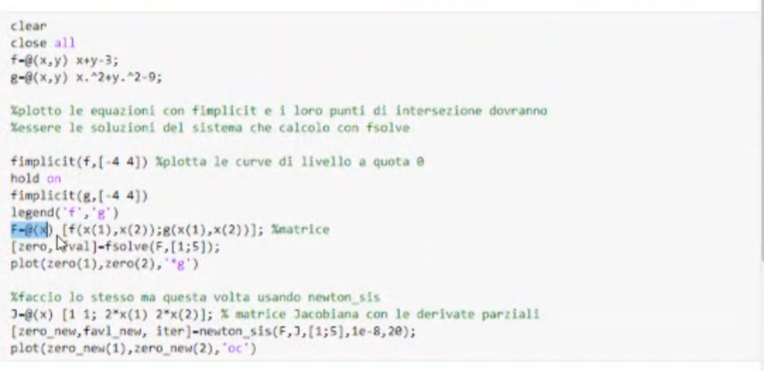

# _____

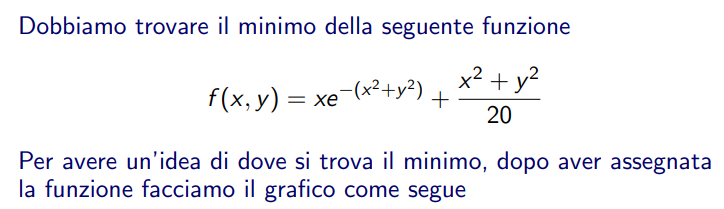

f=@(x,y) x.*exp(-(x.^2+y.^2))+(x.^2+y.^2)/20;
fsurf(f,[-2,2],'ShowContours','on')
fcontour(f,[-2,2])

% per usare Fminsearch come segue 
fun=@(x) f(x(1),x(2));
opt=optimset('Display','iter');
[x,fval]=fminsearch(fun,[-0.5;0],opt)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -0.3769         
     1            3        -0.384745         initial simplex
     2            4        -0.384745         reflect
     3            6        -0.396592         expand
     4            8        -0.400606         expand
     5           10        -0.404889         reflect
     6           12        -0.405204         reflect
     7           14        -0.405204         contract outside
     8           16        -0.405204         contract inside
     9           18        -0.405205         contract inside
    10           20        -0.405218         contract outside
    11           22        -0.405237         contract inside
    12           23        -0.405237         reflect
    13           25        -0.405237         contract inside
    14           27        -0.405237         contract inside
    15           29        -0.405237         contract inside
    16           31        -0.

x =    -0.6690
   -0.0001


fval = -0.4052

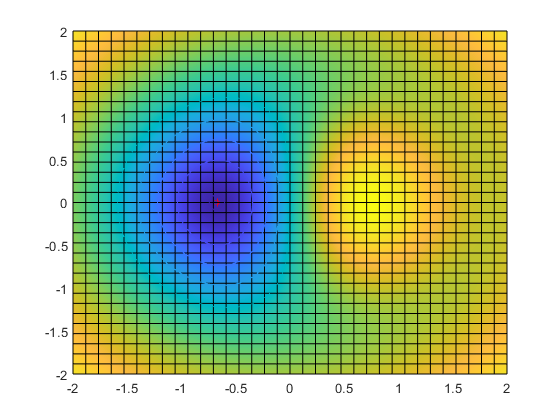

% sono le cordiante del minimo
hold on
plot3(x(1),x(2),fval,'*r')


[x,fval]=fminunc(fun,[-0.5;0],opt)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          -0.3769                         0.339
     1           6        -0.379694              1          0.286  
     2           9        -0.405023              1         0.0284  
     3          12        -0.405233              1        0.00386  
     4          15        -0.405237              1       3.17e-05  
     5          18        -0.405237              1       3.35e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

x =    -0.6691
    0.0000


fval = -0.4052

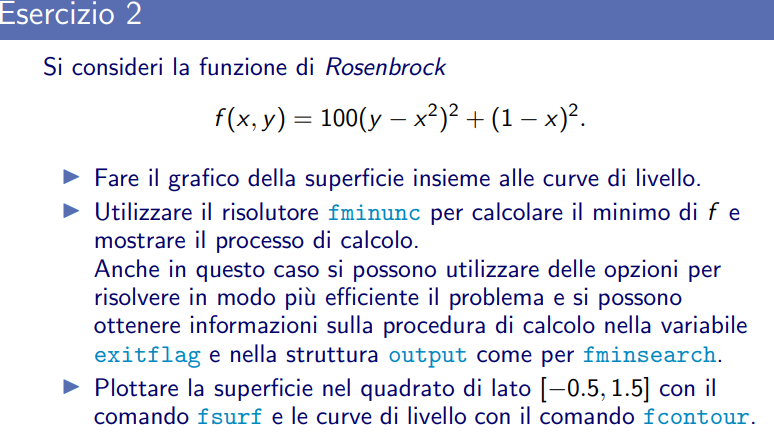

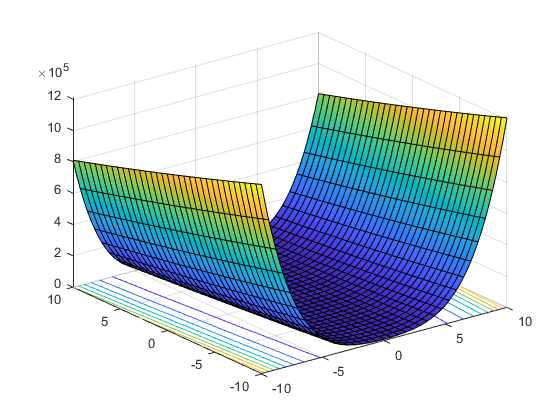

R=@(x,y) 100*(y-x.^2).^2+(1-x).^2;
fsurf(R,[-10,10],'ShowContours','on')

fR=@(x) R(x(1),x(2));
options=optimoptions('fminunc','Display','iter');
[x,fval,exitflag,output]=fminunc(fR,[-1.2,1],options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3             24.2                           216
     1           9          4.28049    0.000861873           15.2  
     2          12          4.12869              1              3  
     3          15          4.12069              1            1.5  
     4          18           4.1173              1           1.62  
     5          21          4.08429              1           5.72  
     6          24          4.02491              1           10.4  
     7          27           3.9034              1           17.4  
     8          30           3.7588              1           20.1  
     9          33          3.41694              1           19.9  
    10          36          2.88624              1           11.9  
    11          39           2.4428              1           9.78  
    12          42          1.93707              

disp(x)

    1.0000    1.0000


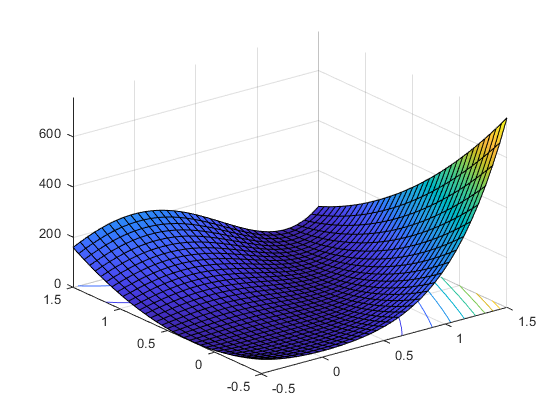

fsurf(R,[-0.5,1.5],'ShowContours','on')

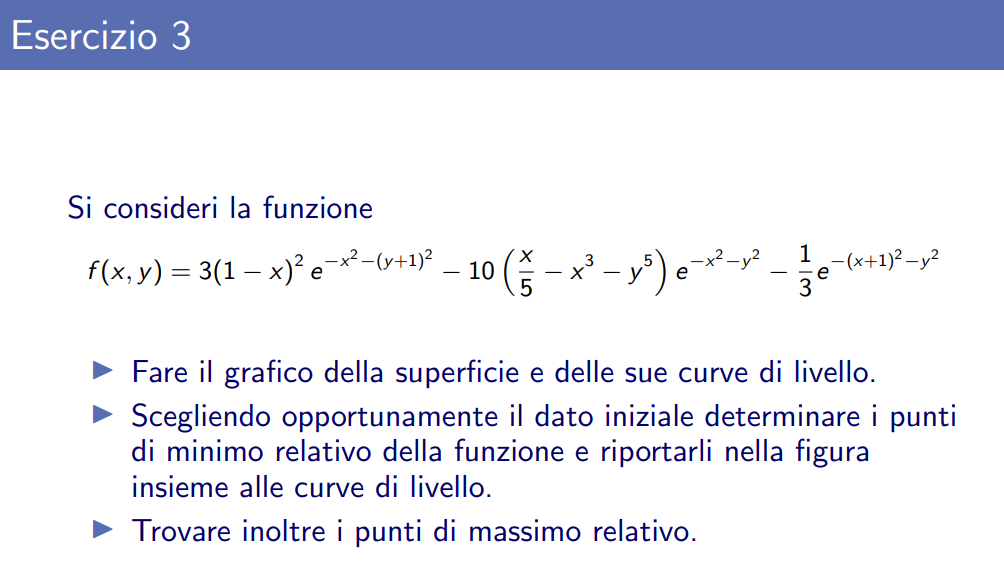

clear all
close all
f = @(x, y)  (3*(1-x).^2*exp(-x.^2-(y+1).^2) )-(10*(x./5 - x.^3 -y.^5).*exp(-x.^2-y.^2))-1/3*exp(-(x+1).^2-y.^2)

f = function_handle with value:
    @(x,y)(3*(1-x).^2*exp(-x.^2-(y+1).^2))-(10*(x./5-x.^3-y.^5).*exp(-x.^2-y.^2))-1/3*exp(-(x+1).^2-y.^2)

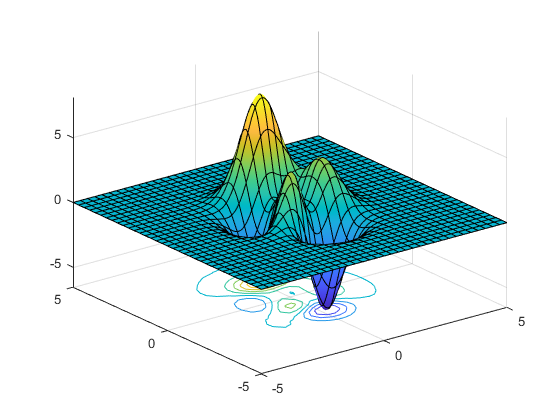

fsurf( f,'ShowContours','on')

fcontour(f)

# passaggio fondamentale per dire che x e y sono variabili e che devo essere ottimizzate per trovare il minimo

fR=@(x) f(x(1),x(2));
options=optimoptions('fminunc','Display','iter');
hold on 
x=fminunc(fR,[0.3,-2],options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3         -4.86897                          7.07
     1           9         -6.46409      0.0419683           2.16  
     2          12         -6.50473              1           1.63  
     3          15         -6.55102              1         0.0688  
     4          18         -6.55113              1        0.00261  
     5          21         -6.55113              1        0.00011  
     6          24         -6.55113              1       2.09e-06  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<<a href = "matlab

x =     0.2283   -1.6255


plot(x(1),x(2),'or')
x=fminunc(fR,[-2,0],options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3         -1.33269                          3.05
     1           9         -2.97343       0.213879           1.22  
     2          12         -3.01771              1          0.744  
     3          15         -3.04533              1           0.36  
     4          21         -3.04952       0.440955         0.0718  
     5          24         -3.04985              1        0.00483  
     6          27         -3.04985              1       9.86e-06  
     7          30         -3.04985              1       1.77e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

x =    -1.3474    0.2045


plot(x(1),x(2),'or')
x=fminunc(fR,[0,0],options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3         0.981012                          3.96
     1           9        0.0289423      0.0663178          0.927  
     2          12       -0.0291808              1          0.666  
     3          15       -0.0569175              1          0.266  
     4          18        -0.064017              1          0.113  
     5          21        -0.064918              1         0.0146  
     6          24       -0.0649358              1       0.000709  
     7          27       -0.0649359              1       1.07e-05  
     8          30       -0.0649359              1       7.25e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

x =     0.2964    0.3202


plot(x(1),x(2),'or')

x=fminunc(fR,[0.05,1.5],options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          7.96694                           2.7
     1           6           0.1858       0.370188           1.68  
     2          21         -6.38337        1.24104           2.41  
     3          33         -6.42122      0.0040779           2.19  
     4          36          -6.5504              1          0.148  
     5          39         -6.55113              1        0.00374  
     6          42         -6.55113              1       9.31e-06  
     7          45         -6.55113              1       3.58e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

x =     0.2283   -1.6255


plot(x(1),x(2),'or')

# per trovare il massimo mi riconduco a un problema  di minimo invertendo la funzione

fR=@(x) -f(x(1),x(2));
x=fminunc(fR,[0.05,1.5],options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3         -7.96694                           2.7
     1           9          -8.0966      0.0370188          0.589  
     2          12         -8.10476              1          0.207  
     3          15         -8.10615              1         0.0426  
     4          18         -8.10621              1        0.00742  
     5          21         -8.10621              1       0.000424  
     6          24         -8.10621              1       8.58e-06  
     7          27         -8.10621              1       2.38e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

x =    -0.0093    1.5814


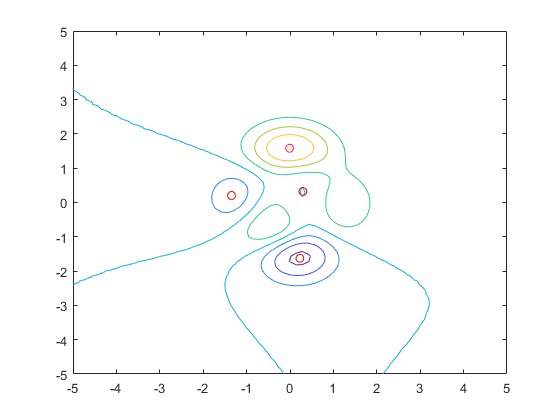

plot(x(1),x(2),'om')